# BME3053C Heartbeat Hackers Final Project

Author: Gabriella Flinn, Jonathan French, Kruze Peacock

Course: BME 3053c Computer Application for BME 

Term: Fall 2023

J. Crayton Pruitt Family Department of Biomedical Engineering 

University of Florida

Email: flinngabriella@ufl.edu 

November 26, 2023. 

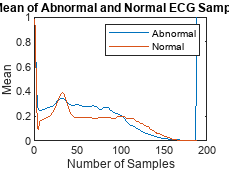


%% Open data 
clc; clear;
abnormal_data=readmatrix('ptbdb_abnormal.csv'); % load the normal and abnormal training data  
normal_data=readmatrix("ptbdb_normal.csv");

%% Visualize data 
mean_abnormal=mean(abnormal_data); %Find the mean of the abnormal data 
mean_normal=mean(normal_data); %Find the mean od the normal data 
x=1:188; %Create x-axis (that correlates to vector length of normal abnormal data
figure(1)
plot(x, mean_abnormal) %Plot mean of abnormal data 
hold on 
plot(x, mean_normal) %Plot mean of normal data on the same graph 
title('Mean of Abnormal and Normal ECG Samples')
legend('Abnormal','Normal')
xlabel('Number of Samples')
ylabel('Mean')

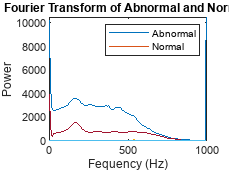


ft_abnormal=abs(fft(abnormal_data)); %Fourier transform of abnormal data 
ft_normal=abs(fft(normal_data)); %Fourier transform of normal dat 
fs=1000; %Sampling frequency 
L=188; %Number of samples 
Hz=(0:L-1)/L*fs;
figure(2)
plot(Hz,ft_abnormal)
hold on
plot(Hz, ft_normal)
title('Fourier Transform of Abnormal and Normal ')
xlabel('Fequency (Hz)')
ylabel('Power')
legend('Abnormal','Normal')


%% Concatenate Abnormal and Normal Data  
total_data=[abnormal_data; normal_data];
labels=total_data(:,188); %Labels found in the last row 1=Abnormal; 0=Normal

%Split Train:Test=70:30
indices=crossvalind('HoldOut',size(total_data,1),0.3);

%% Create Decision Tree Matrix 
rng(101); %Set seed to 101 for reproducibility 
cv=cvpartition(size(total_data,1), 'Holdout', .3);
id_training=cv.training;
x_train=total_data(id_training, 1:187); %Does not include the label (last) column
y_train=labels(id_training);
x_test=total_data(~id_training, 1:187); %Does not include the label (last) column
y_test=labels(~id_training);
dtree=fitctree(x_train,y_train, 'CategoricalPredictors', 'all', 'MinLeafSize', 1, 'MaxNumSplits', 100, 'SplitCriterion', 'deviance');
view(dtree);

Decision tree for classification
1  if x28 in {0.052935 0.059273 0.059621 0.060931 0.065624 0.066167 0.066912 0.069176  0.07017 0.072964 0.072974 0.073287 0.074475 0.076453 0.077763 0.078431 0.078475  0.07893 0.080466 0.081496 0.081626  0.08301 0.083025 0.083523 0.083768 0.084066  0.08433  0.08506 0.086014 0.086984 0.088169 0.088752 0.088819 0.089557 0.091393 0.092214 0.092378 0.092474 0.092862 0.092979 0.093119 0.093282 0.093289 0.093321  0.09391 0.094309 0.094463 0.095156 0.095286 0.095588 0.096567 0.096626 0.097121 0.097501 0.097806 0.097807   0.0986 0.098664 0.099038 0.099968  0.10024  0.10056  0.10066  0.10079  0.10098  0.10116  0.10138  0.10158  0.10191  0.10265   0.1028  0.10323  0.10388  0.10391  0.10464  0.10572  0.10625  0.10625  0.10697  0.10779   0.1078  0.10863  0.10863  0.10873  0.10884  0.10927  0.10953  0.10992  0.11004  0.11029  0.11036  0.11086  0.11104  0.11125  0.11183   0.1122  0.11289  0.11296  0.11367  0.11448  0.11479  0.11504  0.11526  0.11571  0.11626  0.11686


%% Visualize Decision Matrix 
y_predict=predict(dtree,x_test); %The predicted labels 
Confusion=confusionmat(y_test,y_predict);
disp(Confusion)

           9        1202
          18        3136



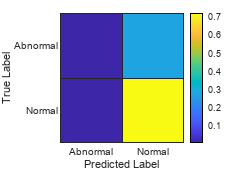

Confusion_normalized=Confusion/sum(Confusion, 'all');
class_labels={'Abnormal', 'Normal'};
figure(3)
heatmap(Confusion_normalized, 'XLabel', 'Predicted Label', 'YLabel', 'True Label', 'ColorbarVisible', 'on', 'XDisplayLabels', class_labels, 'YDisplayLabels', class_labels, 'Colormap', parula, 'FontSize', 8, 'CellLabelColor', 'none');

accuracy = sum(y_predict == total_data(~id_training, end)) / numel(total_data(~id_training, end));
fprintf("accuracy is "+num2str(accuracy))

accuracy is 0.7205


% run an example ekg and display it
example_index = 1; % Change this to the index you want to test
example_data = total_data(example_index, 1:end-1); % Exclude the label column
true_label = labels(example_index);
predicted_label = predict(dtree, example_data);
disp(['Example EKG index: ', num2str(example_index)]);

Example EKG index: 1


disp('A label of 0 refers to a Normal EKG, whhile a label of 1 refers to an abnormal EKG');

A label of 0 refers to a Normal EKG, whhile a label of 1 refers to an abnormal EKG


disp(['True Example Label: ', num2str(true_label)]);

True Example Label: 1


disp(['Predicted Example Label: ', num2str(predicted_label)]);

Predicted Example Label: 1


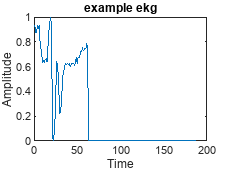


figure;
plot(example_data)
title('example ekg')
xlabel('Time (s)');
ylabel('Amplitude (mV)');